# Aperture size simulations

## Introduction

This live script is for simulating TlF molecules passing through the CeNTREX experiment and specifically to determine the shape, size and position for an aperture to keep the number of molecules hitting the field plates and lens low while maintaining as much signal as possible. We are assuming that the aperture is made of metal and therefore needs to be inserted before the state selection regions. Due to metallic apertures causing adiabatic transfers between moleculat states, this leaves us with the options of placing the aperture either right after the beamsource or after the rotational cooling regions. Where we only care about the rotational quantum number J. Note that this problem could perhaps be circumvented by using apertures made of dielectric material or apertures with voltages on them.

The structure of the script is as follows: We first study the velocity distribution of the molecules that eventually make it to the detection region. Based on this we'll get an approximate shape for the apertures and use this as a starting point to study the effect of the size of apertures placed at different positions on the number of molecules that make it to the detection region, and hit the field plates or lens. We'll then decide on an optimal size and study the effects of various non-ideal scenarious: what if the lens is not on, what if the velocity distribution of the molecule beam is not as expected, what if the aperture is off-center (and others?). Finally we'll also calculate the mean free path of the molecules for varying pressure inside the apparatus and estimate what effect this would have on the accumulation of TlF on the apparatus.

## Velocity distributions

We'll first figure out the x,y - velocity distributions of the molecules that end up making it through the beamline to the detection region. This is done by getting the velocities from a file that was generated earlier based on a beamline with no apertures:

%First load the velocities
load('velocities_39254.mat')

s = size(v_alive{1});

v = zeros(length(v_alive),s(1),s(2));

for i = 1:length(v_alive)
    v(i,:,:) = v_alive{i};
end

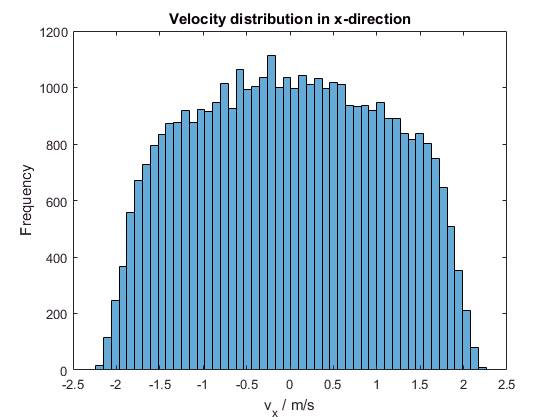

%First plot histograms of velocities before lens
%Plot histogram of x and y- velocities first
figure
histogram(v(:,1,1),'NumBins',50)
xlabel('v_x / m/s')
ylabel('Frequency')
title("Velocity distribution in x-direction")

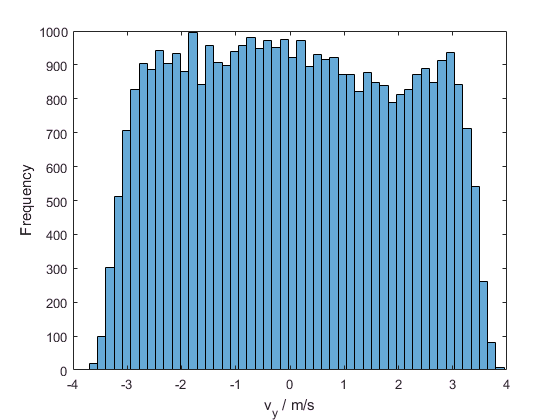


figure
histogram(v(:,2,1),'NumBins',50)
xlabel('v_y / m/s')
ylabel('Frequency')

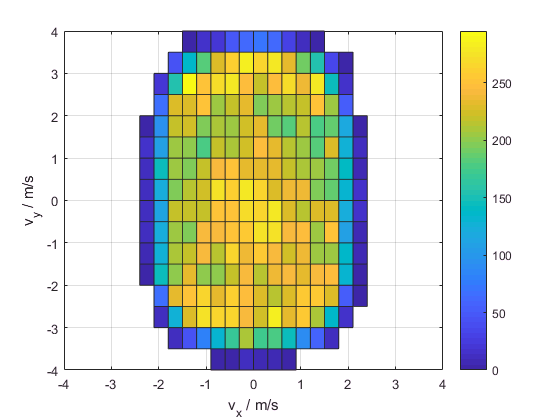


%On the same histogram now:
histogram2(v(:,1,1),v(:,2,1),'DisplayStyle','tile')
xlabel('v_x / m/s')
ylabel('v_y / m/s')
xlim([-4 4])
ylim([-4 4])
colorbar

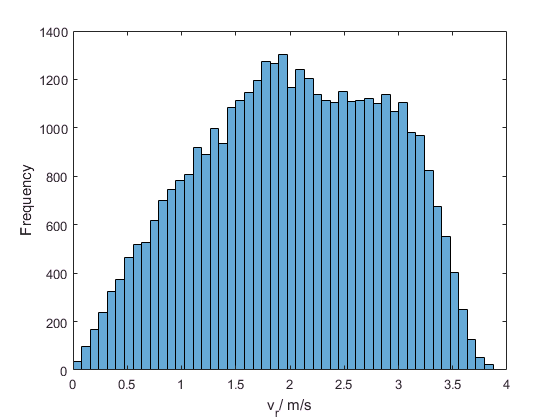


%Next make histogram of radial velocity
v_r = sqrt(v(:,1,:).^2 + v(:,2,:).^2); %calculate radial velocities at each point
figure
histogram(v_r(:,1),'NumBins',50)
xlabel('v_r/ m/s')
ylabel('Frequency')


%What is the max v_r?
max(v_r(:,1))

ans = 3.9104

%What is max v_y?
max(abs(v(:,2,1)))

ans = 3.9099

From the plots above we can see that:

- Distribution of initial x-velocities making it to the detection region is approximately a flat distribution from -2 m/s to +2 m/s

- Similarly, the distribution of y-velocities making it to the detection region is a flat distribution from -3.5 m/s to 3.5 m/s

- The max radial velocity that is captured is 3.9 m/s

- This would indicate that we can make the aperture a rectangle whose sides should be in the ratio of the velocity range

- Thus the aspect ratio of the rectangular aperture should be 2/3.5

%Set the aspect ratio (defined as width over height)
aspect_ratio = 2/3.5

aspect_ratio = 0.5714

For reference, I'm plotting the radial velocity distribution that is used for the source below (derived from assuming Gaussian distributions in x- and y-velocities). The probability distribution function is given by $P\left(v\right)\mathrm{dv}=\frac{v_r }{\sigma^2 }\text{ }\mathrm{exp}\left(-\frac{v_r^2 }{2\sigma^2 }\right)$:

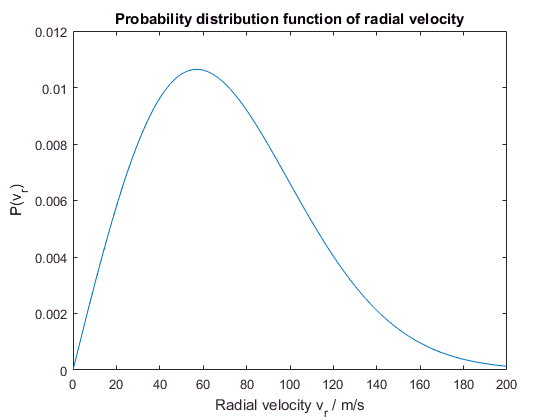

%Set up an array of radial velocities
v = linspace(0,200,1000);
%Set standard deviation for the gaussian's in x and y direction
sigma = 57;
P = v./sigma^2 .* exp(-v.^2/(2*sigma^2));
%Plot the pdf
plot(v,P)
title("Probability distribution function of radial velocity")
xlabel('Radial velocity v_r / m/s')
ylabel('P(v_r)')

We can integrate the pdf to find the maximum fraction of molecules that could in theory be captured. This turns out to be 0.25%.

syms v real
vpa(int(v./sigma^2 * exp(-v^2/(2*sigma^2)),v,0,4))

$$ans = 0.002459267126663957152381932057621$$

## Trajectories and beamline geometry

Before we move on to study the effects of an aperture on the number of molecules making it to the detection region and hitting the field plates and lens, we'll first calculate and plot some trajectories with an aperture placed 3cm after the buffer gas beam source exit just to illustrate what the trajectories look like and what the beamline geometry is.

First we define the geometry of the beamline:

%Beamline parameters (i.e. positions and dimensions of apertures, lenses etc.) (all in meters):
%Measuring z-positions relative to cell aperture

meters_per_inch = 0.0254; %conversion factor from inches to meters

%Cell aperture and zone of freezing dimensions (zone of freezing is the
%region where the molecules "spawn")
cell_aperture.d = meters_per_inch*0.25; %Cell aperture diameter
cell_aperture.z = 0; %Cell aperture position z
zone_of_freezing.z = 1*cell_aperture.d; %position of zone of freezing
zone_of_freezing.d = .02; %diameter of zone of freezing

%4K collimator dimensions (cone)
FourK_collimator.z_1 = 0.325*meters_per_inch; %4K collimator start z position
FourK_collimator.d_1 = 0.232*meters_per_inch; %4K collimator start diameter
FourK_collimator.z_2 = FourK_collimator.z_1 + 1*meters_per_inch; %4K collimator end z position
FourK_collimator.d_2 = 1*meters_per_inch; %4K collimator end diameter
FourK_collimator.type = 'circle'; %Specify cross section type
FourK_collimator.name = 'FourK_collimator';

%4K shield dimensions
FourK_shield.z_1 = FourK_collimator.z_2+ meters_per_inch * 0.375; %4K shield z position
FourK_shield.z_2 = FourK_shield.z_1 + meters_per_inch * 0.25; %4K shield z position
FourK_shield.d_1 = meters_per_inch*1; %4K shield aperture diameter
FourK_shield.d_2 = meters_per_inch*1; %4K shield aperture diameter
FourK_shield.type = 'circle'; %Specify cross section type
FourK_shield.name = 'FourK_shield';

%40K shield dimensions
FortyK_shield.z_1 = FourK_shield.z_2 + meters_per_inch * 1.25; %40K shield z position
FortyK_shield.z_2 = FortyK_shield.z_1 + meters_per_inch * .25; %40K shield z position
FortyK_shield.d_1 = meters_per_inch*1; %40K shield aperture diameter
FortyK_shield.d_2 = meters_per_inch*1; %40K shield aperture diameter
FortyK_shield.type = 'circle'; %Specify cross section type
FortyK_shield.name = 'FortyK_shield';


%Beam box exit dimensions
BB_exit.z_1 = FortyK_shield.z_2 + meters_per_inch * 2.5; %z position
BB_exit.z_2 = BB_exit.z_1 + meters_per_inch * 0.75; %z position
BB_exit.d_1 = meters_per_inch*4; %diameter of beam box exit
BB_exit.d_2 = BB_exit.d_1; %diameter of beam box exit
BB_exit.type = 'circle'; %Specify cross section type
BB_exit.name = 'BB_exit';

%Aperture dimensions (supposed to be 6 mm high and 3 mm wide)
aperture.z_1 = BB_exit.z_2 + 12.5*meters_per_inch;% 0.03; % 12.5*meters_per_inch; %Take position of aperture to be 3cm from exit of beamsource for now
aperture.z_2 = aperture.z_1; %Take the thickness to be negligible
aperture.h = 16.8e-3; %Height is 6 mm
aperture.w = 2/3.5 * aperture.h; %Width is 3 mm
aperture.x_1 = -aperture.w/2;
aperture.x_2 = aperture.w/2;
aperture.y_1 = -aperture.h/2;
aperture.y_2 = aperture.h/2;
aperture.type = 'square'; %Specify cross section type (called square even if it is actually rectangular...)
aperture.name = 'aperture';

%Lens dimensions
source_to_lens_distance = BB_exit.z_2 + meters_per_inch*25; %Distance from cell aperture to star of lens
lens.L = 0.6; %length of lens (m)
lens.d_1 = 1.75*meters_per_inch; %Lens bore diameter = allowed position within lens before escaping
lens.d_2 = lens.d_1; %Lens bore diameter = allowed position within lens before escaping
lens.z_1 = source_to_lens_distance; %position of lens start
lens.z_2 = lens.z_1 + lens.L; %Lens end position
lens.dz = 0.001; %step size within lens
lens.V = 30000; %lens voltage
lens.electrode_d = lens.d_1; %electrode diameter
lens.type = 'lens';
lens.name = 'lens';

%Field plates
aperture_to_field_plate_distance = 0.05; %Distance from field plate aperture to field plates
field_plate.L = 3.000; %length of interaction region
field_plate.z_1 = 1.7727; %position of interaction region start
field_plate.z_2 = field_plate.z_1 + field_plate.L; %position of interaction region end
field_plate.spacing = 0.02; %distance between field plates
field_plate.x_1 = -field_plate.spacing/2; %y-position of lower FP
field_plate.x_2 = +field_plate.spacing/2; %y-position of upper FP
field_plate.y_1 = -5; %not sure what the x-limits should be
field_plate.y_2 = 5; %not sure what the x-limits should be
field_plate.type = 'fplate';
field_plate.name = 'field_plate';


%Detection region
field_plate_to_detection_region_distance = 12.5*meters_per_inch; %Distance from lens to detection region
detection_region.L = 0.05; %length of detection region
detection_region.z_1 = field_plate.z_2 + field_plate_to_detection_region_distance;
detection_region.z_2 = detection_region.z_1 + detection_region.L;
detection_region.h = 0.03; %height of detection region
detection_region.w = 0.01; %width of detection region
detection_region.x_1 = -detection_region.w/2;
detection_region.x_2 =  detection_region.w/2;
detection_region.y_1 = -detection_region.h/2;
detection_region.y_2 = detection_region.h/2;
detection_region.type = 'square';
detection_region.name = 'detection_region';

%Next we put all of the previously defined structures into another structure called beamline geometry. Make
%sure to enter the beamline elements in the correct order (i.e. 1st element along beamline corresponds to 1st index)
beamline_geometry{1} = FourK_collimator;
beamline_geometry{2} = FourK_shield;
beamline_geometry{3} = FortyK_shield;
beamline_geometry{4} = BB_exit;
beamline_geometry{5} = aperture;
beamline_geometry{6} = lens;
beamline_geometry{7} = field_plate;
beamline_geometry{8} = detection_region;

Next we define the beam properties. The velocities in the beam are assumed to be described by Gaussians with mean of 200m/s and std.dev. of 13 m/s for the longitudinal velocity, and $\mu =0$ with $\sigma =57\text{ }\mathrm{m}/\mathrm{s}$ for the transverse direction. The intial spatial distribution of the beam is taken to be a 1cm diameter circle filled uniformly:

beam.v_z = 200; %longitudinal velocity (m/s)
beam.sigma_v_z = 13; %spread in longitudinal velocity (m/s)
beam.v_t = 0; %transverse velocities should be zero on average but with some spread
beam.sigma_v_x = 57; %spread in x velocity (m/s)
beam.sigma_v_y = beam.sigma_v_x; %spread in y velocity (m/s)

beam.d = 0.01; %initial diameter of beam

Next we specify the properties of the molecule in question (TlF, need to specify J value)

%Molecule parameters
molecule.m = (204.38+19.00)*1.67e-27; %TlF molecule mass in kg
molecule.J = 2; %Rotational quantum number of molecule (m_J = 0 by assumption)

Now we can run the simulation of the trajectories:

addpath('../Functions') %Need to add the path that contains all the functions
N_molecules = 1e6; %Set number of trajectories to calculate
%Start clock and then call the function that is used to calculate the trajectories
store_trajectories = true;
tic
[trajectories1, counts] = trajectories(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
toc

Elapsed time is 34.855613 seconds.


Next we plot the trajectories:

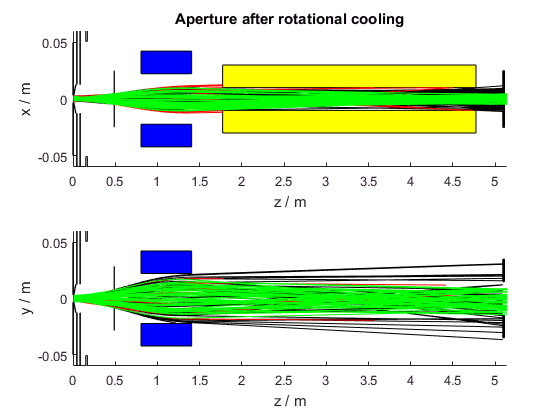

%Plot trajectories x vs z
    figure
    
    subplot(2,1,1)
    hold on
    title('Aperture after rotational cooling')
    %Plot cell aperture
    plot([0 0],[cell_aperture.d/2 0.05],'k','linewidth',1)
    plot([0 0],[-cell_aperture.d/2 -0.05],'k','linewidth',1)
    %Plot 4K collimator
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[FourK_collimator.d_1/2 FourK_collimator.d_2/2],'k','linewidth',1)
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[-FourK_collimator.d_1/2 -FourK_collimator.d_2/2],'k','linewidth',1)
    %Plot 4K shield
    rectangle('Position',[FourK_shield.z_1 FourK_shield.d_1/2 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FourK_shield.z_1 -FourK_shield.d_1/2-1 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[FourK_shield.d_1/2 0.05],'k','linewidth',4)
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[-FourK_shield.d_1/2 -0.05],'k','linewidth',4)
    %Plot 40K shield
    rectangle('Position',[FortyK_shield.z_1 FortyK_shield.d_1/2 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FortyK_shield.z_1 -FortyK_shield.d_1/2-1 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot beambox exit
    rectangle('Position',[BB_exit.z_1 BB_exit.d_1/2 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[BB_exit.z_1 -BB_exit.d_1/2-1 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot lens
    rectangle('Position',[lens.z_1 lens.d_1/2 lens.L 0.02],'facecolor','b')
    rectangle('Position',[lens.z_1 -lens.d_1/2-0.02 lens.L 0.02],'facecolor','b')
    %Plot field plate aperture
    rectangle('Position',[aperture.z_1 aperture.x_2 0.002 0.02],'facecolor','black')
    rectangle('Position',[aperture.z_1 aperture.x_1-0.02 0.002 0.02],'facecolor','black')
    %     plot([aperture.z_1 aperture.z_2],[aperture.d_1/2 0.05],'k','linewidth',1)
    %     plot([aperture.z_1 aperture.z_2],[-aperture.d_1/2 -0.05],'k','linewidth',1)
    %Plot field plates
    rectangle('Position',[field_plate.z_1 field_plate.x_2 field_plate.L 0.02],'facecolor','y')
    rectangle('Position',[field_plate.z_1 field_plate.x_1-0.02 field_plate.L 0.02],'facecolor','y')
    %Plot detection region entrance
    rectangle('Position',[detection_region.z_1 detection_region.x_2 0.02 0.02],'facecolor','black')
    rectangle('Position',[detection_region.z_1 detection_region.x_1-0.02 0.02 0.02],'facecolor','black')
    
    %Plot the trajectories
         
    z_dr = squeeze(trajectories1.detection_region(:,3,:)).';
    x_dr = squeeze(trajectories1.detection_region(:,1,:)).';
    plot(z_dr,x_dr,'k')
    
    z_lens = squeeze(trajectories1.lens(:,3,:)).';
    x_lens = squeeze(trajectories1.lens(:,1,:)).';
    plot(z_lens,x_lens,'k') 
    
    
    z_fp = squeeze(trajectories1.field_plate(:,3,:)).';
    x_fp = squeeze(trajectories1.field_plate(:,1,:)).';
    plot(z_fp,x_fp,'r')    
    
    z_detected = squeeze(trajectories1.detected(:,3,:)).';
    x_detected = squeeze(trajectories1.detected(:,1,:)).';
    plot(z_detected,x_detected,'g')
    
    
    %set axis ranges and labels
    ylim([-0.06 0.06])
    xlim([0 detection_region.z_2])
    xlabel('z / m')
    ylabel('x / m')
    hold off
    

    %Plot trajectories y vs z
    %figure(2)
    subplot(2,1,2)
    hold on
    %Plot cell aperture
    plot([0 0],[cell_aperture.d/2 0.05],'k','linewidth',1)
    plot([0 0],[-cell_aperture.d/2 -0.05],'k','linewidth',1)
    %Plot 4K collimator
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[FourK_collimator.d_1/2 FourK_collimator.d_2/2],'k','linewidth',1)
    plot([FourK_collimator.z_1 FourK_collimator.z_2],[-FourK_collimator.d_1/2 -FourK_collimator.d_2/2],'k','linewidth',1)
    %Plot 4K shield
    rectangle('Position',[FourK_shield.z_1 FourK_shield.d_1/2 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FourK_shield.z_1 -FourK_shield.d_1/2-1 FourK_shield.z_2-FourK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[FourK_shield.d_1/2 0.05],'k','linewidth',4)
    %     plot([FourK_shield.z_1 FourK_shield.z_2],[-FourK_shield.d_1/2 -0.05],'k','linewidth',4)
    %Plot 40K shield
    rectangle('Position',[FortyK_shield.z_1 FortyK_shield.d_1/2 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[FortyK_shield.z_1 -FortyK_shield.d_1/2-1 FortyK_shield.z_2-FortyK_shield.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot beambox exit
    rectangle('Position',[BB_exit.z_1 BB_exit.d_1/2 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    rectangle('Position',[BB_exit.z_1 -BB_exit.d_1/2-1 BB_exit.z_2-BB_exit.z_1 1],'FaceColor',[0.85 0.85 0.85])
    %Plot lens
    rectangle('Position',[lens.z_1 lens.d_1/2 lens.L 0.02],'facecolor','b')
    rectangle('Position',[lens.z_1 -lens.d_1/2-0.02 lens.L 0.02],'facecolor','b')
    %Plot field plate aperture
    rectangle('Position',[aperture.z_1 aperture.y_2 0.002 0.02],'facecolor','black')
    rectangle('Position',[aperture.z_1 aperture.y_1-0.02 0.002 0.02],'facecolor','black')
    %     plot([aperture.z_1 aperture.z_2],[aperture.d_1/2 0.05],'k','linewidth',1)
    %     plot([aperture.z_1 aperture.z_2],[-aperture.d_1/2 -0.05],'k','linewidth',1)
    %Plot field plates
    rectangle('Position',[field_plate.z_1 field_plate.y_2 field_plate.L 0.02],'facecolor','y')
    rectangle('Position',[field_plate.z_1 field_plate.y_1-0.02 field_plate.L 0.02],'facecolor','y')
    %Plot detection region entrance
    rectangle('Position',[detection_region.z_1 detection_region.y_2 0.02 0.02],'facecolor','black')
    rectangle('Position',[detection_region.z_1 detection_region.y_1-0.02 0.02 0.02],'facecolor','black')
    
    z_dr = squeeze(trajectories1.detection_region(:,3,:)).';
    y_dr = squeeze(trajectories1.detection_region(:,2,:)).';
    plot(z_dr,y_dr,'k')
    
    z_lens = squeeze(trajectories1.lens(:,3,:)).';
    y_lens = squeeze(trajectories1.lens(:,2,:)).';
    plot(z_lens,y_lens,'k')
    
    
    z_fp = squeeze(trajectories1.field_plate(:,3,:)).';
    y_fp = squeeze(trajectories1.field_plate(:,2,:)).';
    plot(z_fp,y_fp,'r')
    
    z_detected = squeeze(trajectories1.detected(:,3,:)).';
    y_detected = squeeze(trajectories1.detected(:,2,:)).';
    plot(z_detected,y_detected,'g')

    ylim([-0.06 0.06])
    xlim([0 detection_region.z_2])
    xlabel('z / m')
    ylabel('y / m')
    hold off

## Size and position of aperture

We'll now move on to studying what the size and position of the aperture should be. The position is limited by the fact that we don't want to have apertures after the state selection microwave regions. The possible positions are therefore:

- Right after (i.e. 3 cm) after the beam source exit. This corresponds to 19.38 cm from the zone of freezing. Then for a y-velocity of 3.5 m/s the suitable aperture height would be 2 * 3.4 mm = 6.8 mm. See calculation below.

%Calculate distance from zone of freezing to aperture
distance = BB_exit.z_2 - zone_of_freezing.z + 0.03 %distance in m

distance = 0.1938


%Calculate how much a molecule with y-velocity of 3.5 m/s would have diverged at this point assuming longitudinal velocity of 200 m/s
v_y  = 3.5;
v_z = 200;
delta_y = distance/v_z * v_y

delta_y = 0.0034

       2.  In between the first two microwave regions (i.e. after rotational colling but before state selection for electrostatic lens). Corresponds to 48.13 cm from zone of freezing to the aperture, which would make aperture height 2 * 8.4mm = 16.8 mm

%Calculate the distance from zone of freezing to aperture for this case
distance = BB_exit.z_2 - zone_of_freezing.z + 12.5*meters_per_inch

distance = 0.4813


%Calculate how much a molecule with y-velocity of 3.5 m/s would have diverged at this point assuming longitudinal velocity of 200 m/s
v_y  = 3.5;
v_z = 200;
delta_y = distance/v_z * v_y

delta_y = 0.0084

## Effect of varying aperture size

Now want to check what the effect of the aperture is. We'll first have the aperture right next to the beamsource and then in between the microwave regions (12.5'' from the beamsource). The idea is to loop over different aperture sizes and compare the numbers of molecules that hit each element for different sizes of aperture to find some acceptable compromise. 

Before this, however, we will perform the calculation without an aperture to have a point of reference. For N = 1e5 molecules we get 2984 detected, 4536 hitting the field plates and 622276 hitting the lens.

%Set number of molecules to be simulated
N_molecules = 5e7;
%Set aperture size to 1m
%Define the coordinates of the aperture
aperture.h = 1;
aperture.w = 1;
aperture.x_1 = -aperture.w/2;
aperture.x_2 = aperture.w/2;
aperture.y_1 = -aperture.h/2;
aperture.y_2 = aperture.h/2;

%Update the beamline geometry
beamline_geometry{5} = aperture;

%call the trajectory function
store_trajectories = false;
tic
disp("Started calculation at: ")

Started calculation at: 


datetime('now')

ans = datetime
   28-Aug-2018 17:49:16


[~, counts_no_aperture] = trajectories_parallelized(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
toc

Elapsed time is 830.857084 seconds.


Next we'll do a loop over varying aperture sizes when the aperture is placed right after the beamsource. 

%Define the range of values to consider for the aperture size
aperture_sizes = [4:0.5:16]*1e-3;
n_after_BS.detected = zeros(length(aperture_sizes),1);
n_after_BS.field_plates = zeros(length(aperture_sizes),1);
n_after_BS.lens = zeros(length(aperture_sizes),1);

%set aperture position to be after the beamsource
aperture.z_1 = BB_exit.z_2 + 0.03;
aperture.z_2 = aperture.z_1;

disp("Started loop at: ")

Started loop at: 


datetime('now')

ans = datetime
   29-Aug-2018 09:33:14


%Start loop
for i = 1:length(aperture_sizes)
    %Define the coordinates of the aperture
    aperture.h = aperture_sizes(i);
    aperture.w = aperture.h * aspect_ratio;
    aperture.x_1 = -aperture.w/2;
    aperture.x_2 = aperture.w/2;
    aperture.y_1 = -aperture.h/2;
    aperture.y_2 = aperture.h/2;
    
    
    
    %update the beamline geometry
    beamline_geometry{5} = aperture;
    
    %call the trajectory function
    store_trajectories = false;
    tic
    [~, counts] = trajectories_parallelized(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
    toc
    
    n_after_BS.detected(i) = counts.detected;
    n_after_BS.field_plates(i) = counts.field_plate;
    n_after_BS.lens(i) = counts.lens;
    
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 3 workers.


Elapsed time is 814.800673 seconds.


Elapsed time is 782.237897 seconds.


Elapsed time is 818.309881 seconds.


Elapsed time is 825.741369 seconds.


Elapsed time is 852.731418 seconds.


Elapsed time is 808.921633 seconds.


Elapsed time is 815.648956 seconds.


Elapsed time is 872.298460 seconds.


Elapsed time is 917.938585 seconds.


Elapsed time is 938.136762 seconds.


Elapsed time is 835.665820 seconds.


Elapsed time is 831.782766 seconds.


Elapsed time is 848.329312 seconds.


Elapsed time is 825.904900 seconds.


Elapsed time is 809.095683 seconds.


Elapsed time is 788.335134 seconds.


Elapsed time is 805.532898 seconds.


Elapsed time is 756.127753 seconds.


Elapsed time is 757.569410 seconds.


Elapsed time is 827.525646 seconds.


Elapsed time is 845.282372 seconds.


Elapsed time is 845.790999 seconds.


Elapsed time is 800.246446 seconds.


Elapsed time is 774.629207 seconds.


Elapsed time is 780.761995 seconds.



n_after_BS.aperture_heights = aperture_sizes;

Plot the results:

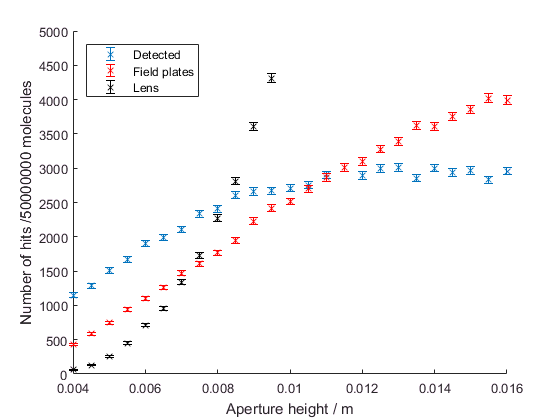

figure 
hold on
errorbar(aperture_sizes,n_after_BS.detected,sqrt(n_after_BS.detected),'x')
errorbar(aperture_sizes,n_after_BS.field_plates,sqrt(n_after_BS.field_plates),'rx')
errorbar(aperture_sizes,n_after_BS.lens,sqrt(n_after_BS.lens),'kx')
xlabel('Aperture height / m')
ylabel(strcat('Number of hits / ',num2str(N_molecules),' molecules'))
ylim([0 5000])
legend('Detected','Field plates','Lens','Location','northwest')

Next we do a loop over the size for an aperture set in between the microwave regions:

%Define the range of values to consider for the aperture size
aperture_sizes = [8:0.5:24]*1e-3;
n_after_RC.detected = zeros(length(aperture_sizes),1);
n_after_RC.field_plates = zeros(length(aperture_sizes),1);
n_after_RC.lens = zeros(length(aperture_sizes),1);

%set aperture position to be in between microwave regions
aperture.z_1 = BB_exit.z_2 + 12.5*meters_per_inch;
aperture.z_2 = aperture.z_1;

disp("Started loop at: ")
datetime('now')

for i = 1:length(aperture_sizes)
    %Define the coordinates of the aperture
    aperture.h = aperture_sizes(i);
    aperture.w = aperture.h * aspect_ratio;
    aperture.x_1 = -aperture.w/2;
    aperture.x_2 = aperture.w/2;
    aperture.y_1 = -aperture.h/2;
    aperture.y_2 = aperture.h/2;
    
    %Update the beamline geometry
    beamline_geometry{5} = aperture;
    
    %Call the trajectory function
    store_trajectories = false;
    tic
    [~, counts2] = trajectories_parallelized(zone_of_freezing,beamline_geometry,lens,beam,molecule,N_molecules,store_trajectories);
    toc
    
    n_after_RC.detected(i) = counts2.detected;
    n_after_RC.field_plates(i) = counts2.field_plate;
    n_after_RC.lens(i) = counts2.lens;
    
end

Elapsed time is 723.499300 seconds.


Elapsed time is 724.111696 seconds.


Elapsed time is 723.304308 seconds.


Elapsed time is 726.771290 seconds.


Elapsed time is 726.339455 seconds.


Elapsed time is 725.517116 seconds.


Elapsed time is 747.924895 seconds.


Elapsed time is 726.655587 seconds.


Elapsed time is 728.608006 seconds.


Elapsed time is 725.561105 seconds.


Elapsed time is 725.740312 seconds.


Elapsed time is 726.545345 seconds.


Elapsed time is 727.796566 seconds.


Elapsed time is 726.312533 seconds.


Elapsed time is 728.064878 seconds.


Elapsed time is 728.765852 seconds.


Elapsed time is 742.600762 seconds.


Elapsed time is 749.694008 seconds.


Elapsed time is 729.764754 seconds.


Elapsed time is 730.035358 seconds.


Elapsed time is 730.017791 seconds.


Elapsed time is 731.286474 seconds.


Elapsed time is 731.216420 seconds.


Elapsed time is 732.544069 seconds.


Elapsed time is 732.188558 seconds.


Elapsed time is 732.079941 seconds.


Elapsed time is 733.191938 seconds.


Elapsed time is 767.693544 seconds.


Elapsed time is 739.114408 seconds.


Elapsed time is 732.563074 seconds.


Elapsed time is 735.102443 seconds.


Elapsed time is 734.941748 seconds.


Elapsed time is 734.820147 seconds.


Plot the results:

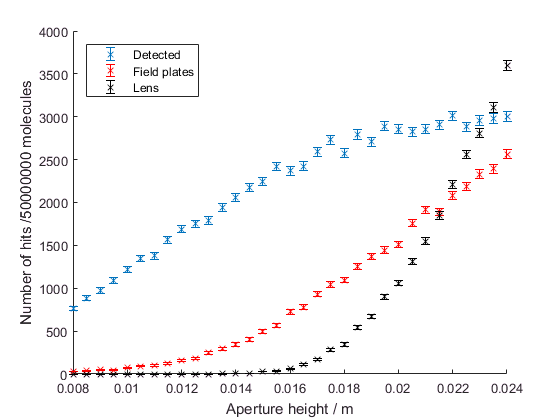

figure 
hold on
errorbar(aperture_sizes,n_after_RC.detected,sqrt(n_after_RC.detected),'x')
errorbar(aperture_sizes,n_after_RC.field_plates,sqrt(n_after_RC.field_plates),'rx')
errorbar(aperture_sizes,n_after_RC.lens,sqrt(n_after_RC.lens),'kx')
xlabel('Aperture height / m')
ylabel(strcat('Number of hits / ',num2str(N_molecules),' molecules'))
legend('Detected','Field plates','Lens','Location','northwest')

Conclusions:

- Having the aperture after the rotational cooling stage is better than having it right after the beamsource. Having them both might of course be even better so that's something to consider.

- Size of aperture: 